# Classifying PPG pulse waves as young or elderly

Photoplethysmogram (PPG) pulse waves differ in shape between young and elderly subjects. The PPG waves of young subjects typically exhibit a second, diastolic peak on the downslope, whereas this disappears with age, and is not often present in PPGs from elderly subjects, as shown in this figure:

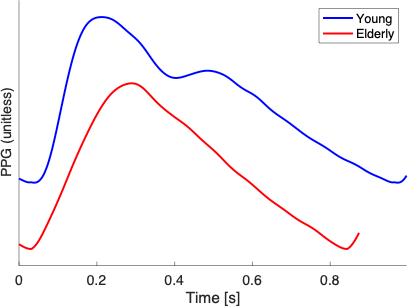

This function trains a deep learning neural network to classify PPG pulse waves as either "young" or "elderly". It uses publicly available, simulated PPG data (described in [this article](https://doi.org/10.1152/ajpheart.00218.2019)).

**Step 0: setup the problem**

Decide whether to classify pulse waves as "young" and "elderly", or to predict the age of the subject.

numerical_age = 0;    % when set to zero this classifies pulse waves as young and elderly
close all;            % close any figures

**Step 1: Loading the data**

Load the PWDB data set (described in [this article](https://doi.org/10.1152/ajpheart.00218.2019), and available [here](https://doi.org/10.5281/zenodo.2633174) - the `pwdb_data.mat` file is required to run this example).

% specify the path of the data file
up.paths.pwdb_data_file = '/Users/petercharlton/Documents/Data/Nektar1D/ageing_sims/pwdb_7/exported_data/pwdb_data.mat';
% load the data file
if ~exist('data','var')
    load(up.paths.pwdb_data_file);
end

**Step 2: Extracting the data**

Extract relevant data from the `data` variable.

old_fs = data.waves.fs;
new_fs = 50;  % new sampling frequency
ds_factor = round(old_fs/new_fs);   % downsampling factor
% downsample each PPG pulse wave
for s = 1 : length(data.waves.PPG_Radial)
    curr_data = downsample(data.waves.PPG_Radial{s}, ds_factor);
    rel_data.sequences{s,1} = curr_data(:)';
end
% copy across the age of each subject
rel_data.age = data.config.age;
rel_data.pwv_SD = data.config.dia_SD;

Split into training and testing data

% identify which data to include in the training and testing datasets
even_els = rem(1:length(rel_data.age),2)==0; even_els = even_els(:);
if ~numerical_age
    % only include data from subjects aged 25 to 75 with physiologically
    % plausible haemodynamics.
    rel_subjs_young = find(rel_data.age == 25 & data.plausibility.plausibility_log);
    rel_subjs_elderly = find(rel_data.age == 75 & data.plausibility.plausibility_log);
    young_train_els = rel_subjs_young(1:2:(2*(floor(length(rel_subjs_young)/2))));
    young_test_els = rel_subjs_young(2:2:(2*(floor(length(rel_subjs_young)/2))));
    elderly_train_els = rel_subjs_elderly(1:2:(2*(floor(length(rel_subjs_elderly)/2))));
    elderly_test_els = rel_subjs_elderly(2:2:(2*(floor(length(rel_subjs_elderly)/2))));
    train_els = [young_train_els; elderly_train_els];
    test_els = [young_test_els; elderly_test_els];
else
    rel_subjs = rel_data.age > 20;
    train_els = even_els & (rel_subjs);
    test_els = ~even_els & (rel_subjs);
end
% extract a training dataset
train_data.sequences = rel_data.sequences(train_els);
train_data.age = categorical(rel_data.age(train_els));
train_data.age_num = rel_data.age(train_els);
train_data.pwv_SD = rel_data.pwv_SD(train_els);
fprintf('Training data: %d subjects (%d young and %d elderly)', length(train_data.age), sum(train_data.age == "25"), sum(train_data.age == "75"));

Training data: 635 subjects (356 young and 279 elderly)

% extract a testing dataset
test_data.sequences = rel_data.sequences(test_els);
test_data.age = categorical(rel_data.age(test_els));
test_data.age_num = rel_data.age(test_els);
test_data.pwv_SD = rel_data.pwv_SD(test_els);
fprintf('Testing data: %d subjects (%d young and %d elderly)', length(test_data.age), sum(test_data.age == "25"), sum(test_data.age == "75"));

Testing data: 635 subjects (356 young and 279 elderly)

**Step 3: Inspecting the pulse wave data**

The predictor variable is contained in `train_data.sequences` (and `test_data.sequences`). These are cell arrays of matrices with one row (since there is only one predictor variable, the PPG), and a variable number of columns (according to the number of PPG samples for each subject).

The response variable is contained in `train_data.age` (and `test_data.age`). These are categorical vectors of labels 25 and 75 years old.

Here is an example of young and elderly PPG pulse waves from the simulated dataset:

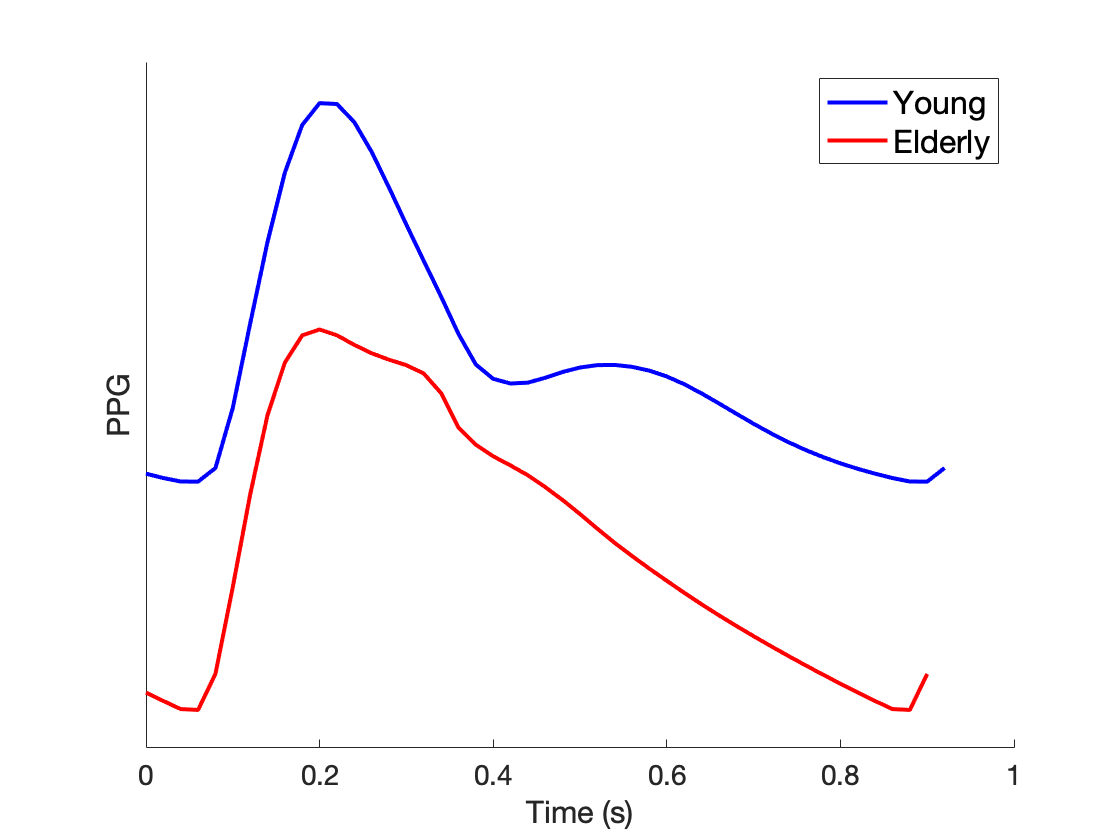

figure
% Plot young pulse wave
no_els_either_side = 2;
rel_el = find(train_data.age_num==25,1);
y_pw = [train_data.sequences{rel_el}(end-no_els_either_side:end), train_data.sequences{rel_el}, train_data.sequences{rel_el}(1:no_els_either_side)]+0.6;
plot((0:length(y_pw)-1)/new_fs, y_pw, 'b', 'LineWidth',2)
hold on
% Plot elderly pulse wave
rel_el = find(train_data.age_num==75,1);
e_pw = [train_data.sequences{rel_el}(end-no_els_either_side:end), train_data.sequences{rel_el}, train_data.sequences{rel_el}(1:no_els_either_side)];
plot((0:length(e_pw)-1)/new_fs, e_pw, 'r', 'LineWidth',2)
% tidy up plot
xlabel('Time (s)', 'FontSize', 16)
ylabel('PPG', 'FontSize', 16)
ylim([-0.1, 1.7])
legend({'Young', 'Elderly'}, 'FontSize', 16), box off, set(gca, 'YTick', [], 'FontSize', 14)

The pulse waves exhibited similar changes with age to those observed in healthy volunteers: most markedly, the diastolic peak disappears with age. (see [this article](https://doi.org/10.1152/ajpheart.00218.2019) for a comparison between pulse waves from young and elderly subjects)

**Step 4: Defining a neural network**

We now define the architecture of the neural network. A long short-term memory (LSTM) recurrent neural network is used, as this is suitable for time series data (in this case, PPG pulse waves). The input layer normalises PPG pulse waves to have zero mean and unit standard deviation.

% options
inputSize = 1;          % the number of features in the input data (there is only one input feature: the PPG)
numHiddenLayers = 100;   % the number of hidden layers
numClasses = 2;         % the number of classes in the data (young and elderly)

% define neural network layers
layers = [ sequenceInputLayer(inputSize, 'Normalization', 'zscore')           % the input layer: this allows you to input sequence (i.e. time series) data. In this case, these are the PPG pulse waves
    lstmLayer(numHiddenLayers,'OutputMode','last')  % specify a long short-term memory (LSTM) recurrent neural network with the prescribed number of hidden layers
    fullyConnectedLayer(numClasses)                
    softmaxLayer                                   
    classificationLayer];                          % the output layer: this allows you to specify what form the output should take. In this case, the output is a binary classification as one of two classes.

if numerical_age
    numResponses = 1;
    layers = [ sequenceInputLayer(inputSize)           % allows you to input sequence (i.e. time series) data
        lstmLayer(numHiddenLayers,'OutputMode','last')  %
        fullyConnectedLayer(numResponses)                %
        regressionLayer];                              % used for regression problems
end

**Step 5: Specifying training options for the neural network**

This specifies the training options for the neural network.

if ~numerical_age
    maxEpochs = 10;
else
    maxEpochs = 30;
end
miniBatchSize = round(length(train_data.sequences)/(2*10));

options = trainingOptions('adam', ...
    'ExecutionEnvironment','cpu', ...
    'MaxEpochs',maxEpochs, ...
    'MiniBatchSize',miniBatchSize, ...
    'GradientThreshold',1, ...
    'Verbose',false, ...
    'Plots','training-progress');

**Step 6: Training the network**

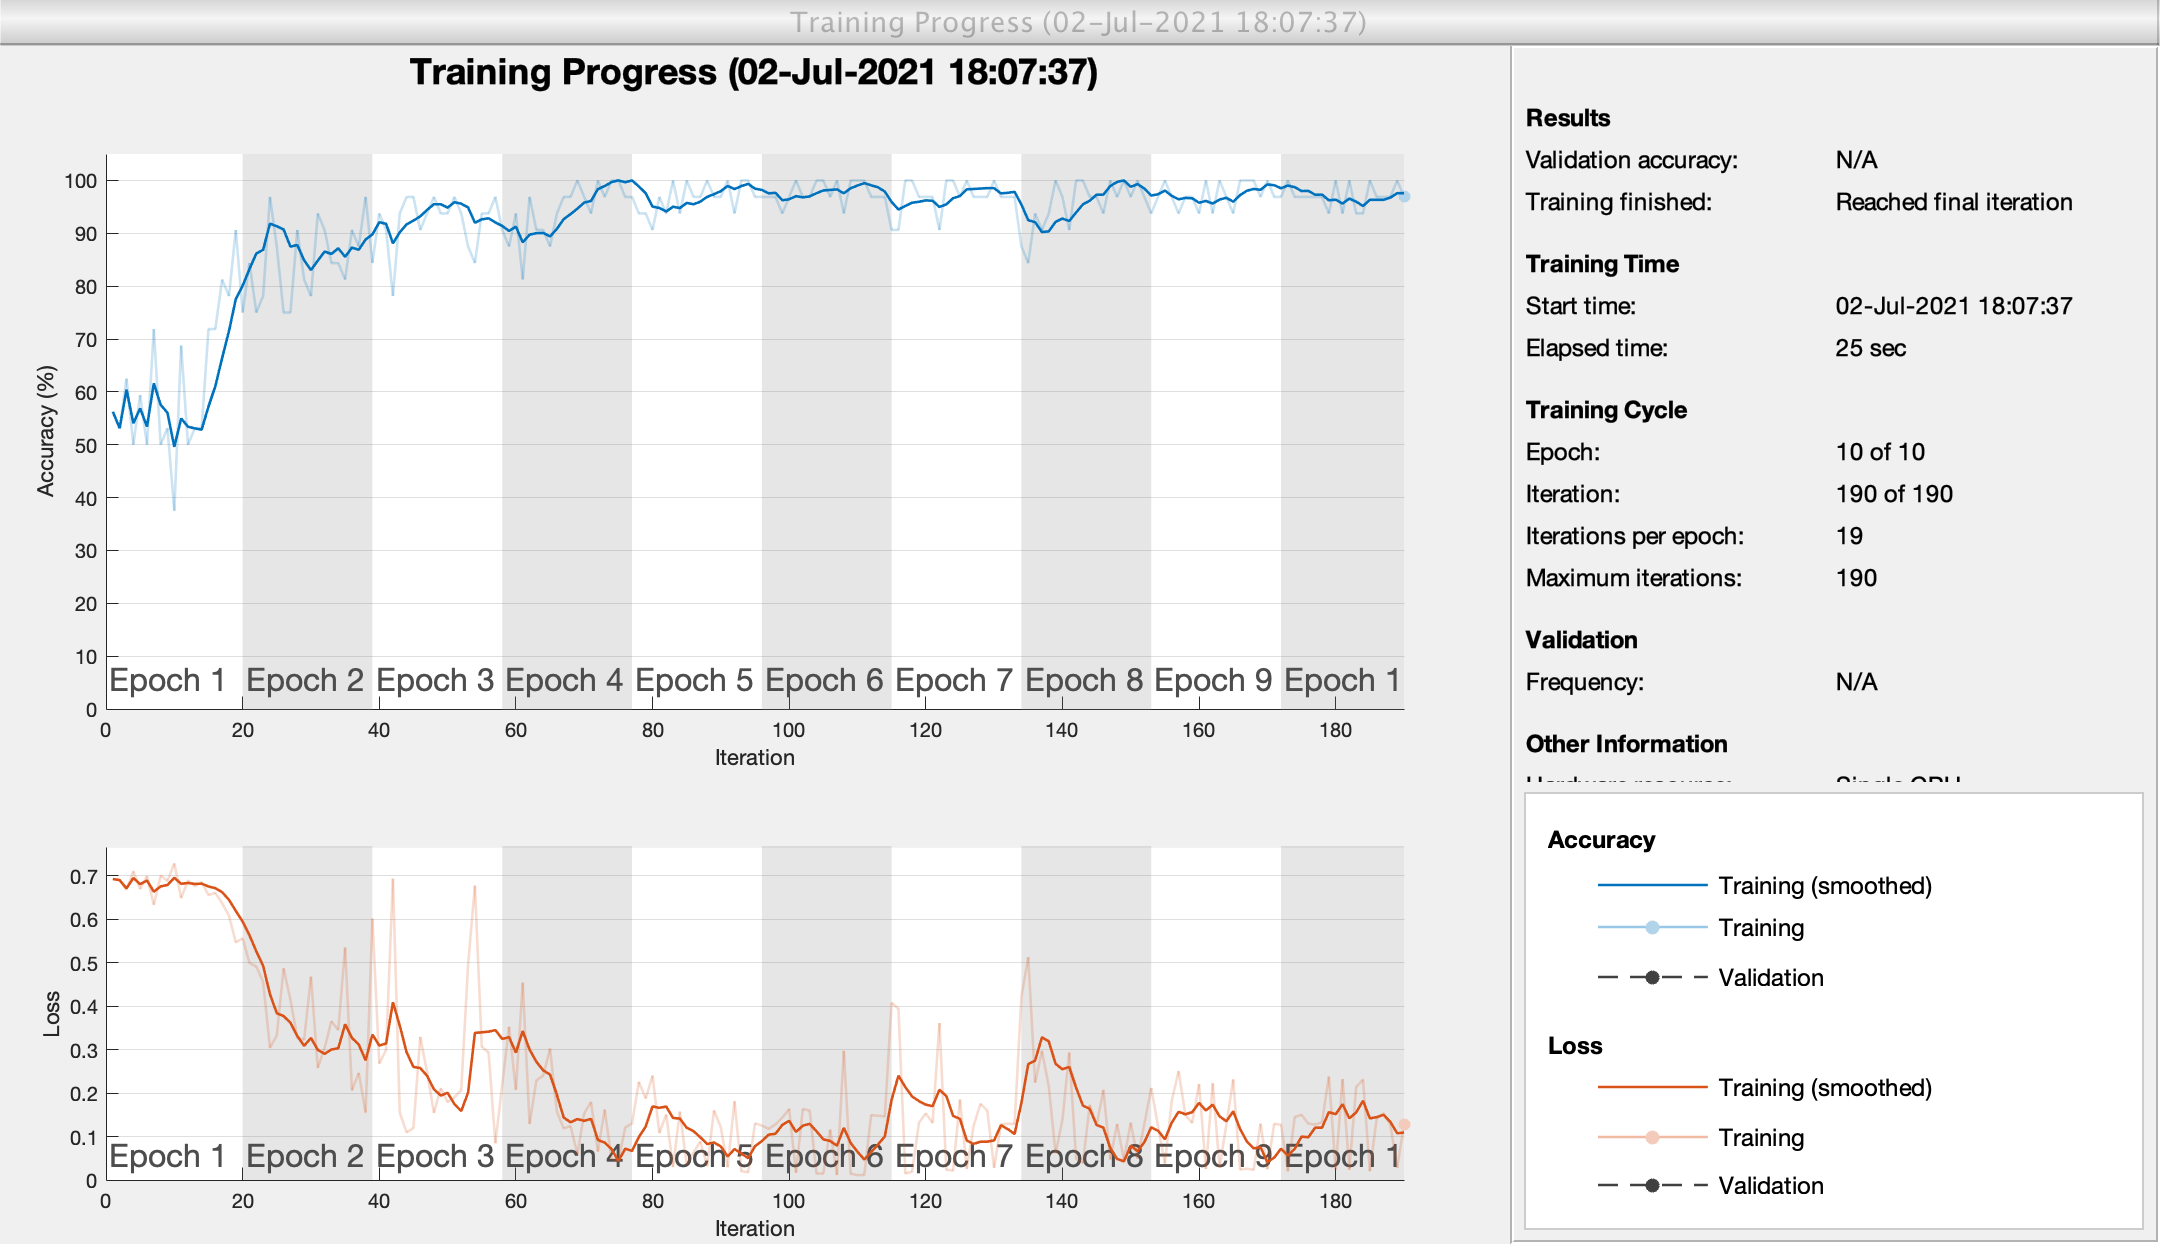

if ~numerical_age
    net = trainNetwork(train_data.sequences,train_data.age,layers,options);
else
    net = trainNetwork(train_data.sequences,train_data.age_num,layers,options);
end

**Step 7: Assessing performance on the testing data**

Use the neural network to classify the subjects in the test dataset as either young or elderly.

if ~numerical_age
    YPred = classify(net,test_data.sequences,'MiniBatchSize',miniBatchSize);
else
    YPred = predict(net,test_data.sequences);
end

Assess the performance of the neural network by calculating the accuracy of these classifications (the proportion of classifications which were correct).

if ~numerical_age
    acc = 100*sum(YPred == test_data.age)./numel(test_data.age);
    fprintf('Accuracy: %.1f %%', acc);
    fprintf('\nNumber of correctly classified PWs: %d out of %d', sum(YPred == test_data.age), length(YPred));
    fprintf('\nNumber of elderly PWs classified as young: %d %%', sum(YPred == "25" & test_data.age == "75"));
    fprintf('\nNumber of young PWs classified as elderly: %d %%', sum(YPred == "75" & test_data.age == "25"));
else
    bias = mean(YPred - test_data.age_num);
    precision = 1.96*std(YPred - test_data.age_num);
end

Accuracy: 94.5 %


Number of correctly classified PWs: 600 out of 635


Number of elderly PWs classified as young: 35 %


Number of young PWs classified as elderly: 0 %

The neural network achieved a high level of accuracy, with all young pulse waves classified correctly, and most elderly pulse waves classified correctly.

**Step 8: Investigate reasons for misclassifications**

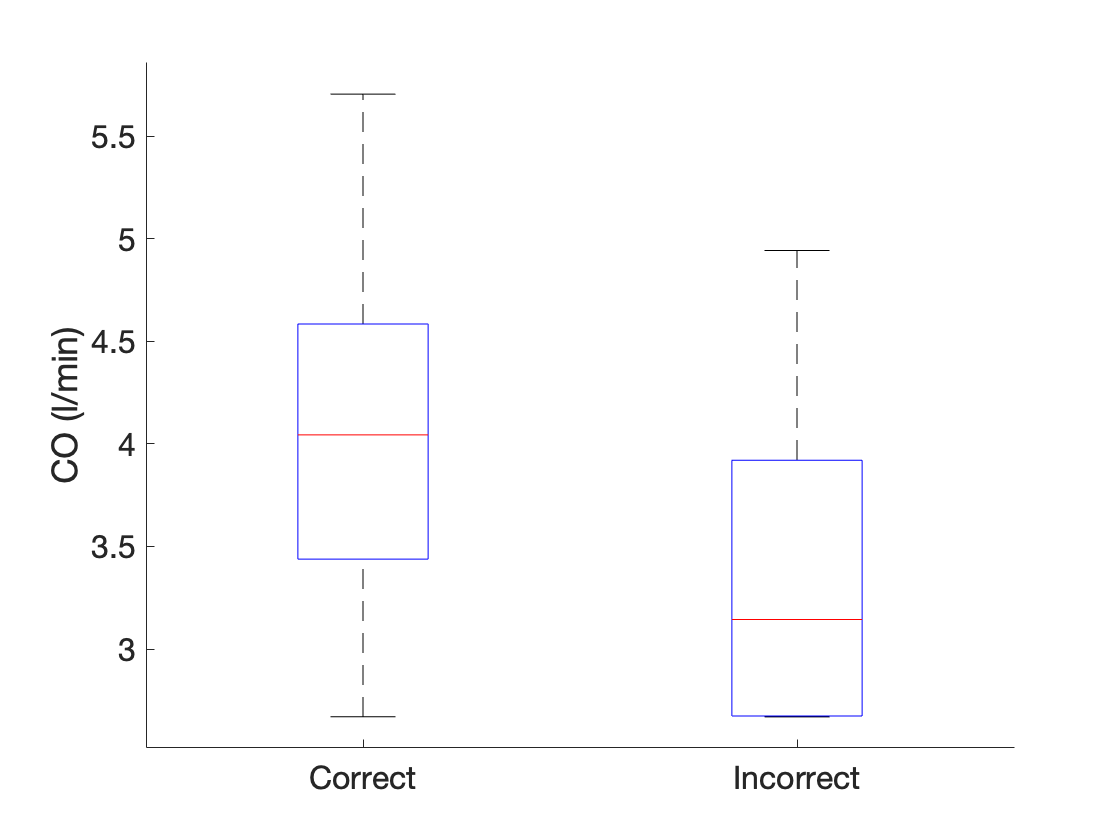

% identify correct and incorrect classifications
incorrect_els = test_els(YPred ~= test_data.age);
correct_elderly_els = setxor(elderly_test_els, incorrect_els); 
% extract cardiac output (CO) values for these
co = extractfield(data.haemods, 'CO');
% make box plot of CO for correctly and incorrectly classified elderly PWs
temp2 = [co(correct_elderly_els), co(incorrect_els)];
close all
boxplot(temp2(:), [zeros(length(correct_elderly_els),1); ones(length(incorrect_els),1)], 'Labels', {'Correct', 'Incorrect'}) ;
% tidy up
ftsize = 16;
ylabel('CO (l/min)', 'FontSize', ftsize);
set(gca, 'FontSize', ftsize), box off

**Source**

*Adapted from the *['Sequence Classification Using Deep Learning'](https://uk.mathworks.com/help/deeplearning/ug/classify-sequence-data-using-lstm-networks.html)* Matlab Example, which can be opened using:*

`openExample('nnet/ClassifySequenceDataUsingLSTMNetworksExample')`

*Version: 1.0 (2nd July 2021)*

*Author: Peter H Charlton (pc657@medschl.cam.ac.uk), University of Cambridge, 2020*